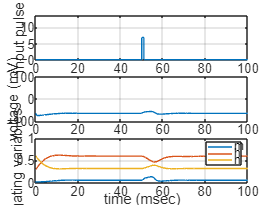

function y = hh(inter, ic, n)
    % Main function for Hodgkin-Huxley model simulation
    % Inputs: time interval 'inter', initial conditions 'ic', number of steps 'n'
    % Example usage: hh([0, 100], [-65, 0, 0.3, 0.6], 2000)
    
    global pa pb pulse
    
    % Get pulse parameters from user
    inp = input('pulse start, end, muamps in [], e.g. [50 51 7]: ');
    pa = inp(1);
    pb = inp(2);
    pulse = inp(3);
    
    % Time grid setup
    a = inter(1);
    b = inter(2);
    h = (b-a)/n;
    
    % Initialize solution arrays
    y(1,:) = ic;
    t(1) = a;
    
    % Main integration loop
    for i = 1:n
        t(i+1) = t(i) + h;
        y(i+1,:) = rk4step(t(i), y(i,:), h);
    end
    
    % Plot results
    subplot(3,1,1);
    plot([a pa pa pb pb b], [0 0 pulse pulse 0 0]);
    grid; axis([0 100 0 2*pulse]);
    ylabel('input pulse');
    
    subplot(3,1,2);
    plot(t, y(:,1)); grid; axis([0 100 -100 100]);
    ylabel('voltage (mV)');
    
    subplot(3,1,3);
    plot(t, y(:,2), t, y(:,3), t, y(:,4)); grid; axis([0 100 0 1]);
    ylabel('gating variables');
    legend('m', 'h', 'n');
    xlabel('time (msec)');
end

function y = rk4step(t, w, h)
    % One step of the Runge-Kutta 4th order method
    s1 = ydot(t, w);
    s2 = ydot(t + h/2, w + h * s1/2);
    s3 = ydot(t + h/2, w + h * s2/2);
    s4 = ydot(t + h, w + h * s3);
    y = w + h * (s1 + 2*s2 + 2*s3 + s4) / 6;
end

function z = ydot(t, w)
    % Defines the Hodgkin-Huxley system dynamics
    global pa pb pulse
    
    % Model parameters
    Cm = 1;        % Membrane capacitance (μF/cm²)
    gNa = 120;     % Maximum sodium conductance (mS/cm²)
    gK = 36;       % Maximum potassium conductance (mS/cm²)
    gL = 0.3;      % Leak conductance (mS/cm²)
    ENa = 50;      % Sodium reversal potential (mV)
    EK = -77;      % Potassium reversal potential (mV)
    EL = -54.4;    % Leak reversal potential (mV)
    
    % Calculate input current (square pulse)
    T = (pa + pb)/2;
    len = pb - pa;
    Iext = pulse * (1 - sign(abs(t-T) - len/2)) / 2;
    
    % Extract state variables
    V = w(1);
    m = w(2);
    h = w(3);
    n = w(4);
    
    % Initialize output vector
    z = zeros(1, 4);
    
    % Voltage equation
    z(1) = (Iext - gNa*m^3*h*(V-ENa) - gK*n^4*(V-EK) - gL*(V-EL))/Cm;
    
    % Gating variable equations
    z(2) = alphaM(V)*(1-m) - betaM(V)*m;    % dm/dt
    z(3) = alphaH(V)*(1-h) - betaH(V)*h;    % dh/dt
    z(4) = alphaN(V)*(1-n) - betaN(V)*n;    % dn/dt
end

% Rate functions for sodium activation gate m
function am = alphaM(V)
    am = (0.1 * (V + 40)) / (1 - exp(-(V + 40)/10));
end

function bm = betaM(V)
    bm = 4 * exp(-(V + 65)/18);
end

% Rate functions for sodium inactivation gate h
function ah = alphaH(V)
    ah = 0.07 * exp(-(V + 65)/20);
end

function bh = betaH(V)
    bh = 1 / (1 + exp(-(V + 35)/10));
end

% Rate functions for potassium activation gate n
function an = alphaN(V)
    an = (0.01 * (V + 55)) / (1 - exp(-(V + 55)/10));
end

function bn = betaN(V)
    bn = 0.125 * exp(-(V + 65)/80);
end

hh([0, 100], [-65, 0, 0.3, 0.6], 2000);